# **MEC3079S: Control Systems**

# Chapter 1 — Introduction

## 1.1 Live scripts

### 1.1.1 Using live scripts

These course notes have been written in `MATLAB live scripts` and comprise text, imagery, and mathematical development, as well as code that is used to generate a variety of useful visualisations. The intention is that you play around with the provided code to get a better understanding of the various concepts that we will cover.

The live scripts have been *sectioned off* (indicated by the thin blue horizontal lines such as just before Section 1.1.2) so that you can run code on a section by section basis. You can use `Run Section `using CMD+ENTER (macOS) or CTRL+ENTER (Windows), or using the `Run Section` button under the `LIVE EDITOR banner `at the top of your screen.

If you want to view the code, select the `Output inline `(figures appear below the text) or `Output on right `(figures appear on the right of the script) button on the top right of the script (see image below). Otherwise, select `Hide code`.

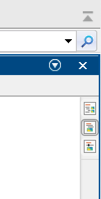

*Live script view options, found at the top right corner of the script: Output on right (top button), Output inline (middle button), Hide code (bottom button).*

You can zoom in/out in `MATLAB live scripts` using CMD+scroll (macOS) or CTRL+scroll (Windows). You can also zoom using the buttons under the `VIEW` banner at the top of the screen. Zooming may help if text/images are too big or small on your monitor.

### 1.1.2 `MATLAB` code blocks

An example of a `MATLAB` code block is shown below. Code blocks will typically consist of parameters that you can change to observe how this affects some kind of visual response (in this case there are numerical sliders that you can play around with). Note that when you alter the slider, all the code blocks within the section will run automatically. You are also welcome to change other parts of the code as part of your experimentation!

s = tf('s');

wn = 42;
zeta = 0.6;

L = wn^2/s/(s+2*zeta*wn);
T = feedback(L,1)

T =
 
         1764
  -------------------
  s^2 + 50.4 s + 1764
 
Continuous-time transfer function.
Model Properties


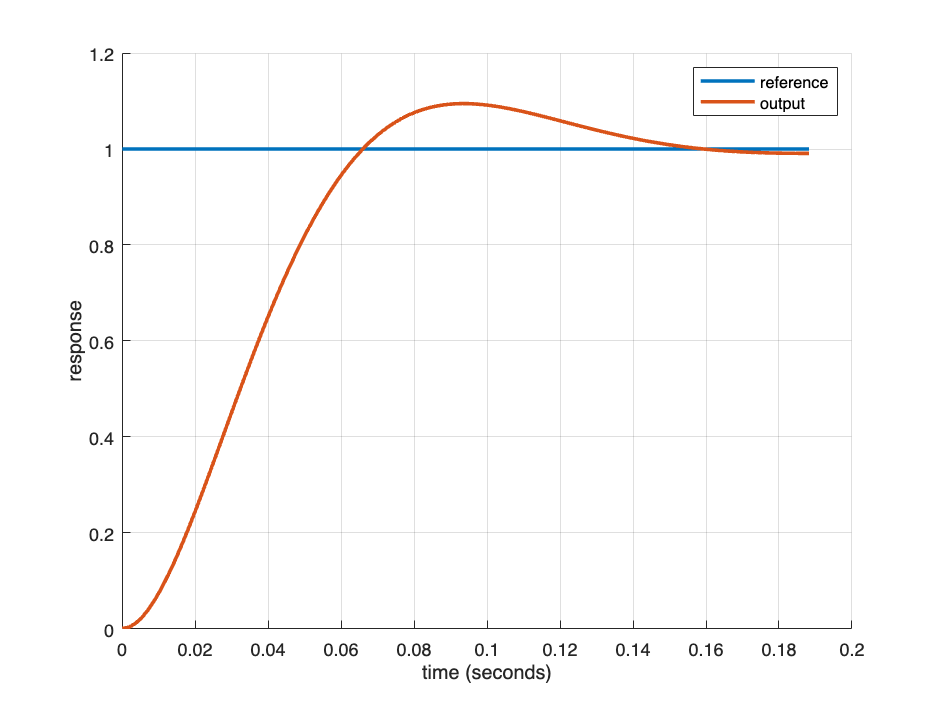


[y,ty] = step(T);
[r,tr] = impulse(1/s,ty(end));

figure, hold on
plot(tr,r,lineWidth=2)
plot(ty,y,lineWidth=2)
grid on
xlabel('time (seconds)')
ylabel('response')
legend('reference','output')

You are not expected to understand the code above just yet, but hopefully in a few weeks this will make some sense to you! Note that you can find more information about a `MATLAB` function by using the `help` function:

%Example
help feedback

 feedback  Feedback connection of two input/output systems. 
 
    M = feedback(M1,M2) computes a closed-loop model M for the feedback loop: 
 
           u --->O---->[ M1 ]----+---> y
                 |               |           y = M * u
                 +-----[ M2 ]<---+
 
    Negative feedback is assumed and the model M maps u to y. To apply 
    positive feedback, use the syntax M = feedback(M1,M2,+1).
 
    M = feedback(M1,M2,FEEDIN,FEEDOUT,SIGN) builds the more general feedback 
    interconnection:
 
                       +------+
           v --------->|      |--------> z
                       |  M1  |
           u --->O---->|      |----+---> y
                 |     +------+    |
                 |                 |
                 +-----[  M2  ]<---+
 
    The vector FEEDIN contains indices into the input vector of M1 and
    specifies which inputs u are involved in the feedback loop. Similarly, 
    FEED

## 1.2 Control systems

This course will introduce you to the wild and wonderous world of **control systems**. The intention is to expose you to various fundamental elements that can be used to *analyse* and *design* control systems. A control system is a fairly vague term that can apply to a range of scenarios. We can think of a control system as a collection of various subsystems that interact with each other to achieve some pre-defined objective. The objective will vary depending on the particular system under consideration, and the means to achieve the goal will be dependent on specifications (usually supplied by a client) and the physical and/or financial limitations attached to the project.

Control systems are all around us and are a fundamental part of our daily lives. Some examples of control systems are:

- The temperature control within an oven.

- The water level control in a toilet cistern.

- Voltage regulation of the AC voltage supplied to houses (e.g. 220 volts).

- Heading and velocity control of an airplaine.

- The position and orientation control of an automous drone

### 1.2.1 Control system definition

A control system consists of subsystems and processes (or *plants*) assembled for the purpose of obtaining a *desired output* with *desired performance*.

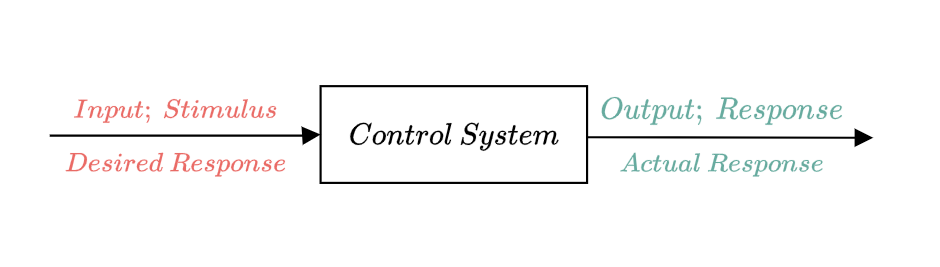

We represent 

- **signals **(e.g. inputs and outputs) with an arrow, where the direction of the arrow indicates the directional flow of the signal

- **systems** (processes or plants) with a block. The output of a system is a result of the interaction between the input signal and system.

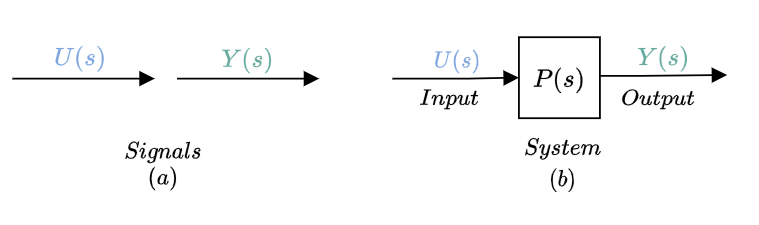

Consider an elevator. When the fourth‐floor button is pressed on the first floor, the elevator rises to the fourth floor with a speed and floor‐leveling accuracy designed for passenger comfort. The push of the fourth‐floor button is an **input** that represents our **desired output **(where we want the elevator to eventually get to), shown as a step signal in the figure below. The **performance** of the elevator can be seen from the elevator response curve in the figure below.

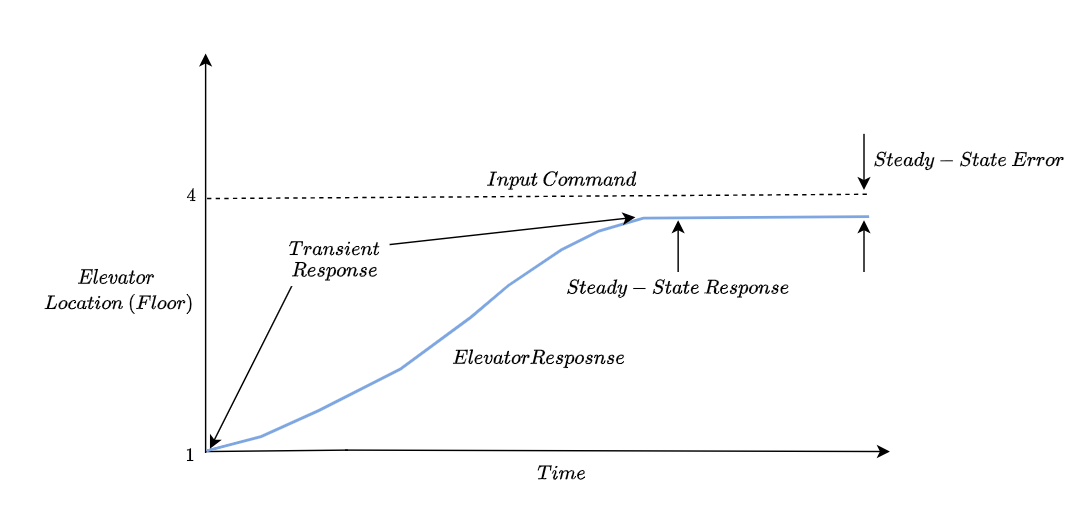

There are two major measures of performance of any system in general:

- Transient response (this is the behaviour of the elevator when in motion).

- Steady-state error (the difference between the desired elevator position and actual elevator position after the elevator stops).

In our example, passenger comfort and passenger patience are dependent upon the transient response. If this response is too fast, passenger comfort is sacrificed; if too slow, passenger patience is sacrificed. The steady‐state error is another important performance specification since passenger safety and convenience would be sacrificed if the elevator did not level properly. A third implicit consideration in control systems is the concept of stability. The transient response and steady-state error conversation would be rendered pointless if the elevator had an unstable response and ended up crashing into the ceiling of the elevator shaft!

### 1.2.2 Advantages of control systems

Control systems have many advantages. Some of the main advantages are summarised below.

- Power amplification and signal conditioning — amplifying and filtering signals such that the best properties of the signal is maintained while avoiding amplifying signal noise (e.g. audio amplifier)

- Automating systems — enabling systems to autonomously complete tasks without the need for human intervention (e.g. assembly line pick and place robot).

- Uncertainty reduction — reducing the effect of parameter variations on the performance of a system (e.g. cruise control of a vehicle with an unknown number of passengers).

- Compensation for disturbances — reducing the effect of disturbances on the control system (e.g. an aircraft autonomously compensating for crosswinds while landing).

- Stability — maintaining stability of a system that would otherwise be unstable (e.g. angle control of an inverted pendulum).

## 1.3 History of control systems

Control systems date back thousands of years, with the first instances being purely mechanical in nature. Some notable milestones are summarised below.

- Liquid-level control (~300 B.C)

- Steam pressure and temperature control (1681)

- Speed control (1745)

- Stability and steering (1868)

- Wright brothers (1903)

- Space Race (1955-1972)

## 1.4 System configurations

There are two major configurations of control systems:

- Open-loop control systems (often also referred to as feedforward control systems),

- Closed-loop control systems (often also referred to as feedback control systems).

### 1.4.1 Open-loop systems

An input (often called a reference signal if it defines a desired value) is applied to the system via an input transducer. The controller drives the plant with the intention of achieving a particular output (controlled variable).

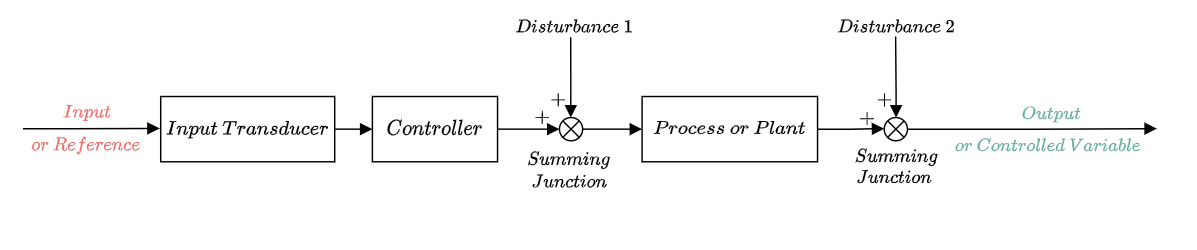

An **open-loop system** is cheap to implement, but it cannot compensate for any disturbances that act on the system. For example, toasters are open‐loop systems, as anyone with burnt toast can attest. The controlled variable (output) of a toaster is the color of the toast. The device is designed with the assumption that the toast will be darker the longer it is subjected to heat. The toaster does not measure the color of the toast; it does not correct for the fact that the toast is rye, white, or sourdough, nor does it correct for the fact that toast comes in different thicknesses. We set the reference signal, which on a toaster usually corresponds to the "toasting time", and then hope that our guess of this input signal will result in a favourable output (an apprpropriately toasted piece of bread).

### 1.4.2 Closed-loop (feedback control) systems

In addition to the open-loop configuration, an output transducer (or sensor) measures the output response and converts it into a form that can be used by the controller.

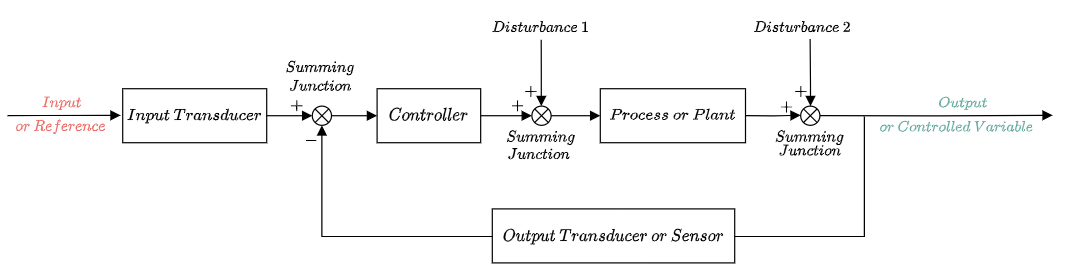

A **closed‐loop system** compensates for disturbances by measuring the output response, feeding that measurement back through a feedback path, and comparing that response to the input at the summing junction. If there is any difference between the two responses, the system drives the plant, via the actuating signal, to make a correction. If there is no difference, the system does not drive the plant, since the plant's response is already the desired response.

In the case of the toaster example, if we were able to measure the colour of the toast (e.g. with a camera), then we could feed this information back to the toaster in order to tell it when to turn off. This would constitute closed-loop control (albeit of a simple form).

### 1.4.3 Open-loop vs closed-loop

Another good comparison of open-loop and closed-loop control is to consider how modern toilets with cisterns refill after the toilet has been flushed. We can imagine that the task is to keep the water level at the desired level, but when the toilet is flushed this acts as a disturbance that results in the cistern quickly emptying. The question is then: how do we determine how long to open the valve from our water supply in order to refill the cistern, and how do we know if the water has reached the correct level?

An *open-loop* implementation, as shown in the left figure below could make use of an estimated flow rate from our water supply to determine the time required to open the valve to let water in, in order to fill the tank to an appropriate level (this require basic integration based on the shape and dimensions of the tank). This seems like a plausible idea, but in reality the flow rate from the water supply will vary depending on the demand in the rest of the house (for example if someone else is showering at the same time). Therefore, we should expect that there will be some non-zero amount of steady-state error when relying on an open-loop control scheme to refill our toilet cistern. Note that this may still be acceptable if a non-zero steady-state error is within the specifications of our toilet.

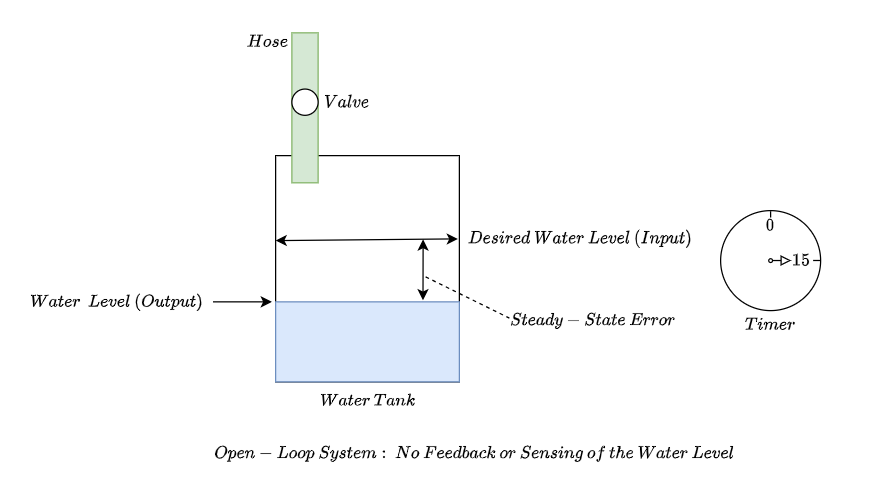      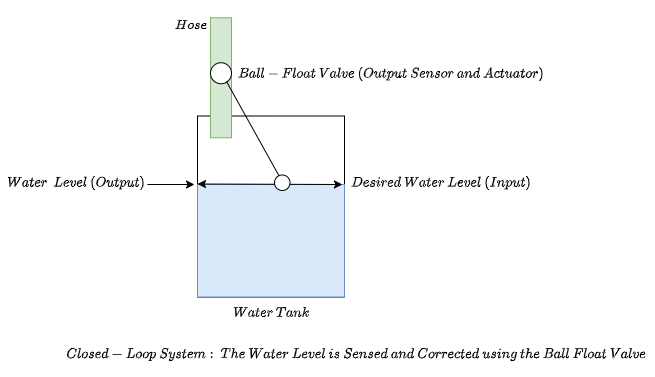

A *closed-loop *implementation makes use of a ball-float valve as shown in the right figure above. When the water level is equal to the desired water level, the float sits at the desired height and keeps the valve closed. When the toilet is flushed and all the water is emptied out the cistern, the float drops to a near-vertical position, which opens the valve. The water then rises based on the open valve, and will only close again when the water reaches the desired height. Note that while the time it takes to fill the cistern may vary depending on the other water loads in the house, the tank will eventually refil to the correct height. Note that while the closed-loop solution definitely seems more practical (and tolerant of uncertainty with regard to flow rate), we did have to add additional components (a ball-float in this case), so our closed-loop solution is more expensive financially. Whether the additional expense is justified would come down to the client requirements.

### 1.4.4 Computer-controlled systems

Modern control systems make use of digital computers, as opposed to using analogue components (e.g. resistors, capactitors, operational amplifiers). Both analogue and digital control systems exist today with varying advantages and disadvantages. The advantages and disadvantages of using digital control systems are summarised below.

Advantages: 

- a single computer can control multiple control systems and control loops

- adjusting control parameters can be done "instantly" via software

- simulation and implementation can be tightly coupled using the same hardware/software environment

Disadvantages:

- digital sampling effects can cause performance and stability degradation

- at the mercy of software/hardware related shortcomings (e.g. stack overflows, processor stall, signal amplitude/bandwidth limits, ADC quantisation)

We will cover methods of converting control schemes into implementable algorithms at the end of this course.

## 1.5 Analysis and design objectives

### **1.5.1 Analysis**

**Analysis** is the process by which a system's performance is determined and understood. For example, we evaluate a system's transient response and steady‐state error to determine if they meet the desired specifications (usually provided by the client). At this stage, we also identify whether the system requires intervention (maybe the system already meets the client's specifications, thereby requiring no intervention) and if intervention is required, what type of control configuration is required (open-loop vs closed-loop).

### 1.5.2 Design

**Design** is the process by which a system's performance is adjusted as required. For example, if a system's transient response and steady‐state error are analyzed and found not to meet the specifications, then we change control parameters or add additional compensators to meet the specifications.

Key considerations:

- Transient response — how quickly does the output response settle after a reference signal is applied, and how oscillatory/erratic is the response during this period.

- Steady-state response — what is the extent of the difference between the reference signal and output signal after the transient period has completed.

- Stability — does the output respond in a stable (non-divergent) manner as a result of all reference signals of interest.

Other considerations: 

- Hardware selection — how do we select components (e.g. sensors, microcontrollers, actuators) such that the system specifications will not be hindered.

- Cost of design — balancing the performance specifications against the cost of the additional components required to achieve the specifications.

- Robust design — designing the control system such that it will perform within the required specifications regardless of disturbances and parameters variations in the system.

### 1.5.3 Design trade-offs

As we will see later in the course, we will have to make a trade-off between the performance we can achieve, and the amount of energy that we can inject into our system. For example, we can try design a control system for a Toyota Corolla that will make it go from $0$ km/hr to $100$ km/hr in a few seconds, but we will end up being fundamentally limited by the amount of power that our engine can produce relative to the car's mass. 

The example below shows that we can make our output response as quick as we want, but at the cost of increased control action. The control action is usually a physical signal, such as a voltage, force/torque, flow rate, or pulse width modulated signal. As with any real-world system, there will be limitations on the control action that is achievable — e.g. the voltage supplied to a system is limited by the power supply available, or the torque produced by an engine is limited by its design.

s = tf('s');
P=1/s;
G = 33;
Ty = P*G/(1+P*G);
Tu = G/(1+P*G);

figure
subplot(2,1,1), step(Ty),title('Output response')
subplot(2,1,2), step(Tu),title('Control action required')

## 1.6 The design process

The **design process** often takes the form as detailed below:

- Convert user requirements into engineering specifications.

- Mathematically model the system under consideration and represent the model using a block diagram (or some other equivalent visualisation).

- If available, confirm the model representation using measurement data.

- Analyse the system using control analysis techniques against the required specifications and identify the required control scheme.

- Design a control scheme and test its viability.

- If the designed control scheme meets the specifications, then the design process is complete, otherwise return to Step 4. 

## 1.7 Computer-aided design

The computer is an integral part of modern control system design, and many computational tools are available for your use. In this course we use `MATLAB` and the `MATLAB Control System Toolbox`, which enables us to quickly analyse, design, and test control systems.

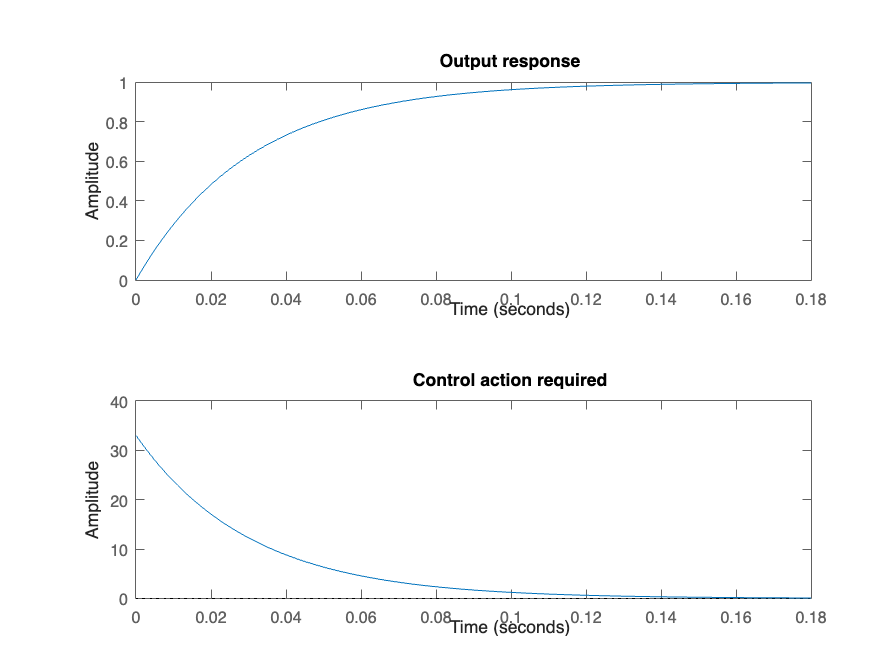

s = tf('s');

w = 2;
z = 0.7071;
P = 1/(s^2/w^2+2*z/w*s+1);

dT = 0.1;
ty = 0:dT:5;

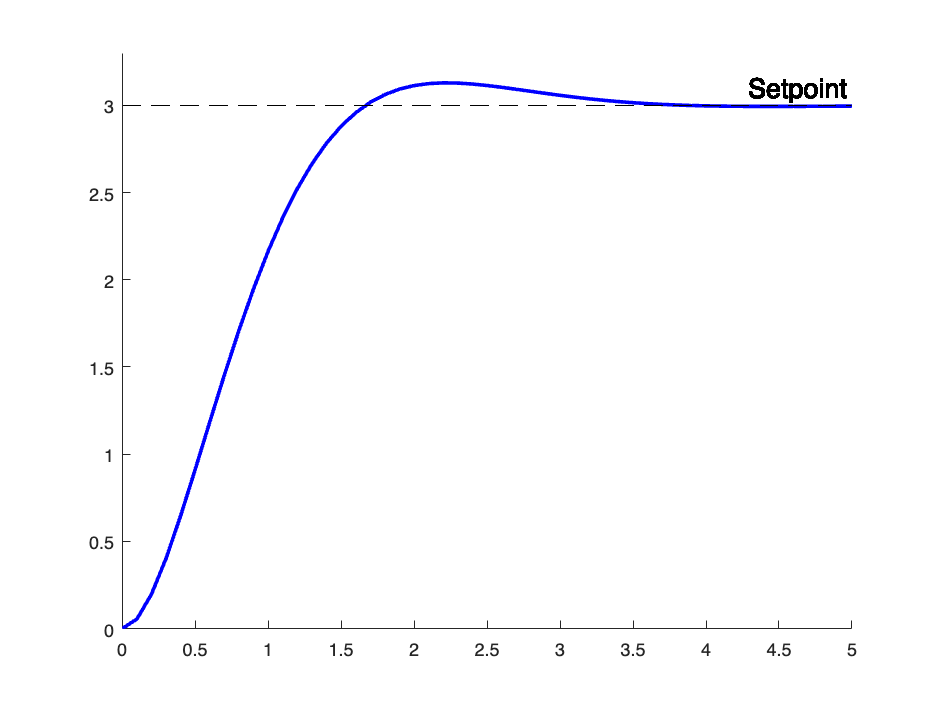

U = 3;
[y,~] = step(P*U,ty);

timer = rateControl(1/dT);

figure, hold on, 
axis([0 5 0 1.1*U])
for i=1:length(ty)
    plot(ty(1:i),y(1:i),'b-',lineWidth=2)
    yline(U,'--k','Setpoint',FontSize=15)
    drawnow
    waitfor(timer);
end

## 1.8 The control systems engineer

Control systems engineering is an exciting field in which to apply your engineering talents, because it cuts across numerous disciplines and numerous functions within those disciplines. The control engineer can be found at the top level of large projects, engaged at the conceptual phase in determining or implementing overall system requirements. These requirements include total system performance specifications, subsystem functions, and the interconnection of these functions, including interface requirements, hardware and software design, and test plans and procedures.

## 1.9 Summary of course content

The course will contain the following chapters:

- Introduction

- Signals and Systems

- Block diagrams

- Modelling in the Laplace domain

- Prediction of system response

- System characterisation

- Frequency-domain analysis

- Feedback control systems

- Stability of closed-loop systems

- Steady-state error

- Frequency-domain design

- Digital control systems

Chapters 1-4 constitute *fundamental* theory development that will be required to tackle the latter chapters. 

Chapters 5-10 are involved with the *analysis* of control systems, with Chapter 8-10 focusing on feedback control systems. 

Finally, Chapters 11-12 (and Chapter 10 to an extent) are concerned with feedback control *design* methodologies.